# load data

task = 'contrLocalBadpt';
folder = '/Users/henry/Documents/local-data';

% load behavioural data table
file = fullfile(folder,task,'derivatives','eeg','ic','compiled-data-struct.mat');
load(file, 'df')
df = struct2table(df);

% load the IC data used with FOOOF 
file = fullfile(folder,task,'derivatives','eeg','ic','timeseries-IC-data.mat');
load(file, 'data')

% load the IC raw data to get the times 
file = fullfile(folder,task,'derivatives','eeg','ic','all_ic.mat');
load(file, 'ic')

times = ic.times;


## find the peak times

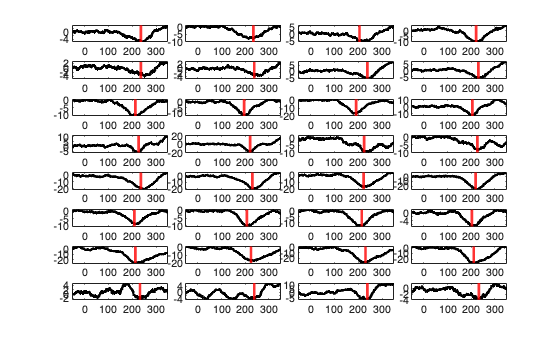

% find the time points to search
toi = [160,240];
tix = find(ic.times >= toi(1) & ic.times <= toi(2));

% window length to average
twin = [-15, 15];

peak_times = nan(8,4);
peaks = nan(1,size(data,2));

ERP = nan(8,4,numel(ic.times));

clf;
tiledlayout(8,4,'tilespacing','tight')
for k = 1:8
    for n = 1:4
        % get the data
        ii = df.sub==k & df.ses==n;
        tmp = data(:,ii);
        erp_peak = mean(tmp,2); 
                
        % plot ERP
        nexttile
        plot(ic.times, erp_peak,'color','k','linewidth',2);
        xlim([-50,350])

        % find the max point 
        [maxErp, maxind] = min((erp_peak(tix)));
        maxtime = ic.times(tix(maxind));
        xline(maxtime, 'r','linewidth',2,'alpha',.8)
         
        peak_times(k,n) = maxtime;

        % store trial level data (average window)
        twin_ix = ic.times >= maxtime+twin(1) & ic.times <= maxtime+twin(2);
        peaks(ii) = mean(data(twin_ix,ii),1);

        ERP(k,n,:) = erp_peak;
    end
end


df.erp_peak = peaks'; 

times = ic.times;
save(fullfile(folder,task,'plot-data','ic-erp.mat'),'ERP','times')


## correlate with phase

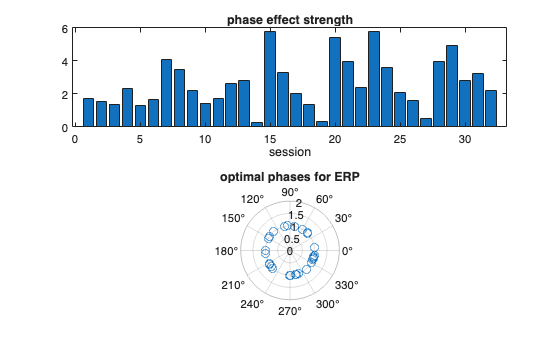

optimal_phase = [];
phase = df.phi_echt;

clf;
tiledlayout(8,4,'tilespacing','tight')
for k = 1:8
    for n = 1:4
        ii = df.sub==k & df.ses==n;
        
        % use only alpha detected trials
        erp_peak = peaks(ii & ~isnan(phase)); 
        ph = phase(ii & ~isnan(phase));
        
        % compute correlation two ways
        [rho, p(k,n)] = circ_corrcl(ph,erp_peak);

        [b,~,~,~,stats] = regress(erp_peak', [ones(size(erp_peak')), sin(ph), cos(ph)]);
        p2(k,n) = stats(3);
        
        % find the maximal phase from coefficients
        optimal_phase(k,n) = atan2(b(2),b(3));
        modulation_amp(k,n) = abs(b(3)+1j*b(2));
        df.phase_offset(ii) = optimal_phase(k,n);
    end
end

clf
nexttile
bar(1:32, modulation_amp(:))
xlabel('session')
title('phase effect strength')

nexttile
polarplot(optimal_phase(:), ones(size(optimal_phase(:))),'o')
title('optimal phases for ERP')


mean(modulation_amp(:)) ./ std(modulation_amp(:))

ans = 1.7454


p = p2;

% stouffer's method
P = normcdf(sum(norminv(p(:))) / sqrt(numel(p)))

P = 5.5429e-04


% fisher's method 
P = 1-chi2cdf(-2*sum(log(p(:))), 2*numel(p))

P = 6.1185e-04

## fit linear model of sin/cos phase

df.cp = cos(df.phi_echt);
df.sp = sin(df.phi_echt); 

m = fitglme(df,'erp_peak~sp+cp + (sp+cp|pid)','covariancepattern','diagonal')

m = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations           19347
    Fixed effects coefficients           3
    Random effects coefficients         96
    Covariance parameters                4
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    erp_peak ~ 1 + cp + sp + (1 + cp + sp | pid)

Model fit statistics:
    AIC           BIC           LogLikelihood    Deviance  
    1.8626e+05    1.8632e+05    -93124           1.8625e+05

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE         tStat      DF       pValue        Lower      Upper  
    {'(Intercept)'}         -11.021     1.2764    -8.6345    19344    6.3504e-18    -13.522    -8.5189
    {'cp'         }         0.46108    0.37069     1.2438    19344       0.21357    -0.2655 


H = zeros(2,numel(m.Coefficients.Name));
H(1,ismember(m.Coefficients.Name, 'cp')) = 1;  
H(2,ismember(m.Coefficients.Name, 'sp')) = 1; 

[pval, F, df1, df2] = coefTest(m,H);
pval

pval = 0.1848

## plot the phase effect

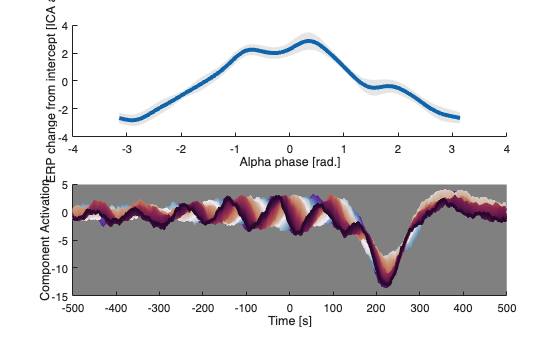

[fe,fenames] = fixedEffects(m); 
[re,renames] = randomEffects(m);

% % extract random effects for optimal phase
% sp_i = fe(ismember(fenames.Name,'sp')) + re(ismember(renames.Name,'sp'));
% cp_i = fe(ismember(fenames.Name,'cp')) + re(ismember(renames.Name,'cp'));
% lm_phase_offset = atan2(sp_i,cp_i);

% extract the intercept for ERP peak amplitudes
intc = fe(ismember(fenames.Name,'(Intercept)')) + re(ismember(renames.Name,'(Intercept)'));

sigma = deg2rad(15);
cdist = @(x1,x2) atan2(sin(x1-x2),cos(x1-x2));

pids = unique(df.pid);
bins = linspace(-pi,pi); 
erp_peak = nan(numel(bins),numel(pids)); 
ERP = nan(numel(times),numel(bins), numel(pids));
for n = 1:numel(pids)
    ind = df.pid==pids(n) & ~isnan(phase);
    phi = cdist(phase(ind),df.phase_offset(ind));  % 
    
    % X = df.erp_peak(ind) - intc(n); % subtract intercept 
    X = df.erp_peak(ind) - mean(df.erp_peak(ind));
    w = exp(cos(cdist(phi,bins))*sigma^-2 - sigma^-2);
    w = w./sum(w,1);
    erp_peak(:,n) = X'*w; 

    ERP(:,:,n) = data(:,ind)*w;
end

clf
nexttile
hold on 
mu = mean(erp_peak,2);
plot(bins, mu, 'linewidth',3)
sem = std(erp_peak,1,2)./sqrt(size(erp_peak,2));
fill([bins,flip(bins)], [mu+sem; flip(mu-sem)]', 'k', 'facealpha',.1,'edgecolor','none')
xlabel('Alpha phase [rad.]')
ylabel('ERP change from intercept [ICA act.]')

nexttile
cols = twilight_shifted(numel(bins)); 
hold on 
for n = 1:numel(bins)
    plot(times, mean(ERP(:,n,:),3), 'color', [cols(n,:),.2], 'linewidth',2)
end
xlim([-500,500])
set(gca, 'Color', ones(1,3)*.5)
xlabel('Time [s]')
ylabel('Component Activation')


save(fullfile(folder,task,'plot-data','phase-erp.mat'),'ERP','times')


%% save 
df = table2struct(df, 'toscalar', true);
save(fullfile(folder,task,'derivatives','eeg','ic','compiled-data-struct.mat'),'df')


## linear model of alpha amplitude

df.x = df.amp_echt;
m = fitglme(df,'erp_peak~ x + (x|pid)')

m = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations           19347
    Fixed effects coefficients           2
    Random effects coefficients         64
    Covariance parameters                4
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    erp_peak ~ 1 + x + (1 + x | pid)

Model fit statistics:
    AIC           BIC           LogLikelihood    Deviance 
    1.8622e+05    1.8626e+05    -93102           1.862e+05

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat     DF       pValue        Lower       Upper  
    {'(Intercept)'}        -12.399       1.3465    -9.208    19345    3.6528e-20     -15.038    -9.7596
    {'x'          }        0.10627     0.039081    2.7193    19345     0.0065475    0.029672    0.18288


anova(m)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat     DF1    DF2      pValue    
    {'(Intercept)'}        84.787    1      19345    3.6528e-20
    {'x'          }        7.3947    1      19345     0.0065475
